# Video Pre-Processing & Draw Bounding Box 

**Aim: **as a general script. 

**Summary**: Starting with a video (.avi), individual frames are extracted and stored in a temporary folder. Then, loop through each individual frame for image processing and bounding boxes are overlaid onto orginal image frame. The overlaid images will be saved to the same temporary folder. 

**Log:** 

**26-Jan-2020; SWC**. Test on: SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi

**27-Jan-2020; SWC**. tested with v2.0 of vidPreprocess function. 

Test on: SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi (test003; test_out003)

Test on: SO5cSt 12uL_23 uL SDS_10 mM 02.avi (test004; test_out004)

clear all 
close all 
clc 

##  1) Load Video

vid_file_name = 'SO5cSt 12uL_23 uL SDS_10 mM 02.avi'; %<-------- user-defined input!!
vid = VideoReader(vid_file_name); %read video 
% make sure video is in same path as codes!!!
totframes = vid.NumFrames %check total num of frames in video

totframes = 531

## 2) Background Generation - Use Median of Frames

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 2.426327 seconds.


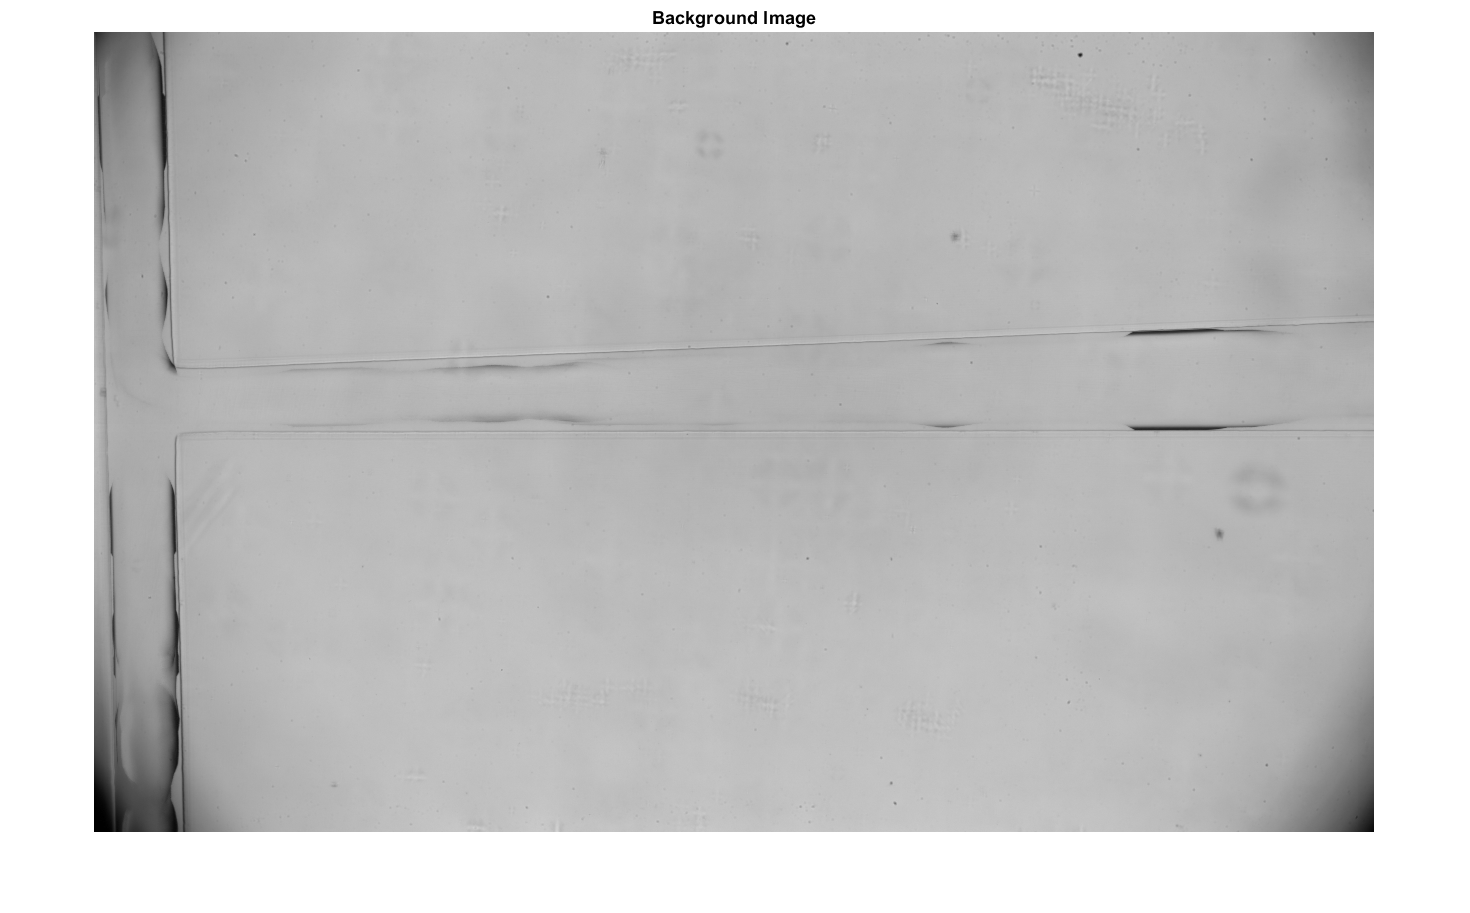


%show generated background 
imshow(med_pix); title("Background Image")

## 3) Extract Video Frames & Save in Temporary Folder 

**Accompanying function file: ***extractVidFrames.m*

*Note: if want to test code, check if the temporary subfolder already exists from previous runs. If so, delete subfolder from the shared drive first before running code.*

- Create temporary folder to store files

mkdir test004 % create new sub-folder  <-------- user-defined input!! (how you would like it to be called, can be anything)
addpath test004 % enable access to subfolder <-------- user-defined input!!

- Define user inputs for function

num_frames = totframes; % number of frames to extract from video <-------- user-defined input!!
file_path = 'D:\SWC-MATLAB\test004\'; %folder to save images in <-------- user-defined input!!

- call function

extractVidFrames(vid_file_name, num_frames, file_path); %extracted video frames saved in temporary subfolder

## 4) Create Labelled Video Frames & Save in Temporary Folder 

**Accompanying function file**: *vidFramePreprocess2.m*

*Note: original video frame images will be overwritten and replaced with 'labelled' frame images. Labelled as in draw bounding boxes *

temp_folder = dir('test004\*.jpg');  %<-------- user-defined input!!

bg = med_pix; %background image - generated earlier
t = 0.2; %treshold value  <-------- user-defined input!!
foldername = 'test004'; % <-------- user-defined input!!
minArea = 1000; % <-------- user-defined input!!
leadEdge = 140; % <-------- user-defined input!!

tic
%loop through each frame in subfolder
for i = 1:numel(temp_folder)
    file = temp_folder(i).name;
    
    vidFramePreprocess2(file, bg, t, minArea, leadEdge, foldername);
end
toc

Elapsed time is 789.098158 seconds.


## 5) Recreate video - with bounding boxes

**Accompanying function file***: createVid.m.*

tic
labelled_vid = createVid('test_out004', vid.FrameRate, num_frames);  % <-------- user-defined input!!
% inputs: (name the file to be saved as, frame rate, total number of frames
% to create video)
toc

Elapsed time is 49.312380 seconds.
